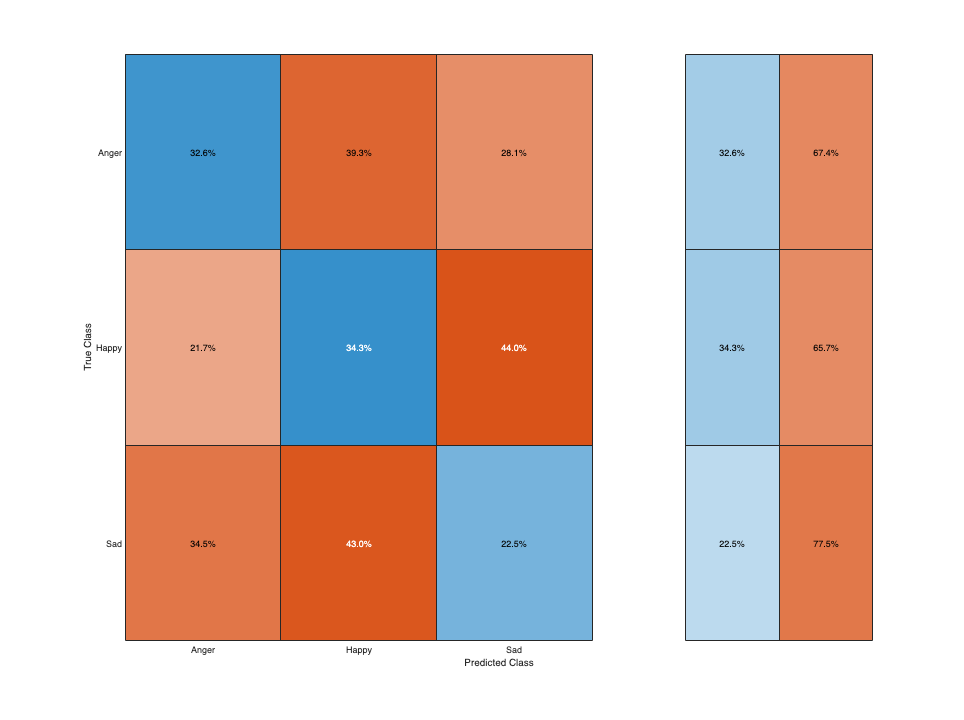

% Load ShEMO (Persian) model and predict on EmoDB (German)
load Workspace_ShEMO.mat net
load Workspace_EmoDB.mat sequencesTrain sequencesTest labelsTrain labelsTest
sequencesAll = vertcat(sequencesTrain, sequencesTest);
labelsAll = vertcat(labelsTrain, labelsTest);
predictionsAll = classify(net, sequencesAll);
labelsAll = removecats(labelsAll);
predictionsAll = removecats(predictionsAll);
figure; confusionchart(labelsAll, predictionsAll,'Normalization','row-normalized','RowSummary','row-normalized');

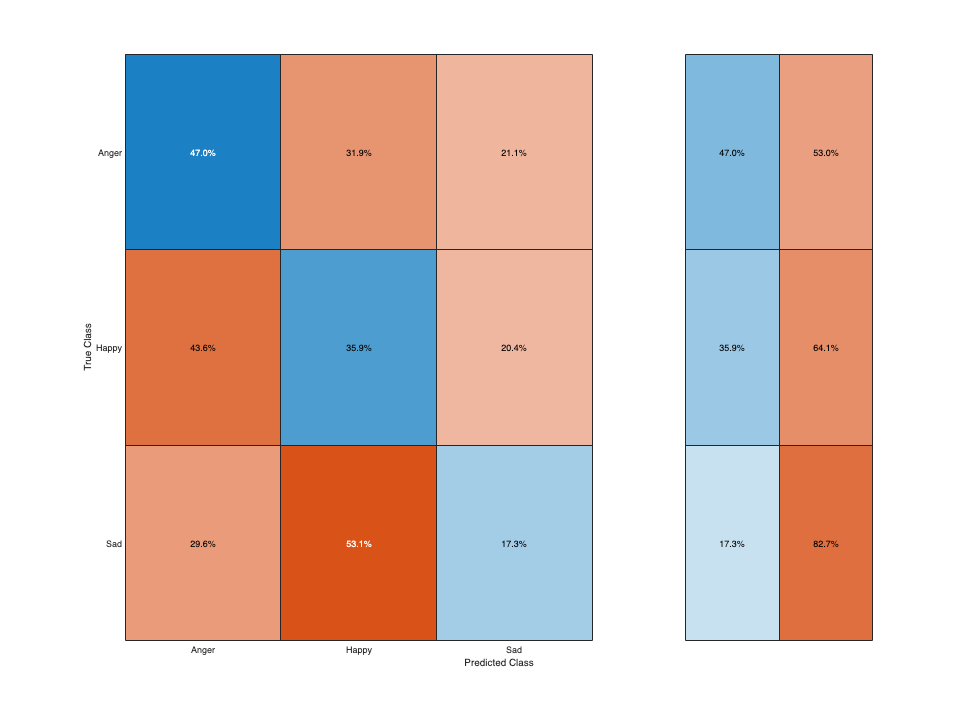

% Load EmoDB (German) model and predict on ShEMO (Persian)
load Workspace_EmoDB.mat net
load Workspace_ShEMO.mat sequencesTrain sequencesTest labelsTrain labelsTest
sequencesAll = vertcat(sequencesTrain, sequencesTest);
labelsAll = vertcat(labelsTrain, labelsTest);
predictionsAll = classify(net, sequencesAll);
labelsAll = removecats(labelsAll);
predictionsAll = removecats(predictionsAll);
figure; confusionchart(labelsAll, predictionsAll,'Normalization','row-normalized','RowSummary','row-normalized');

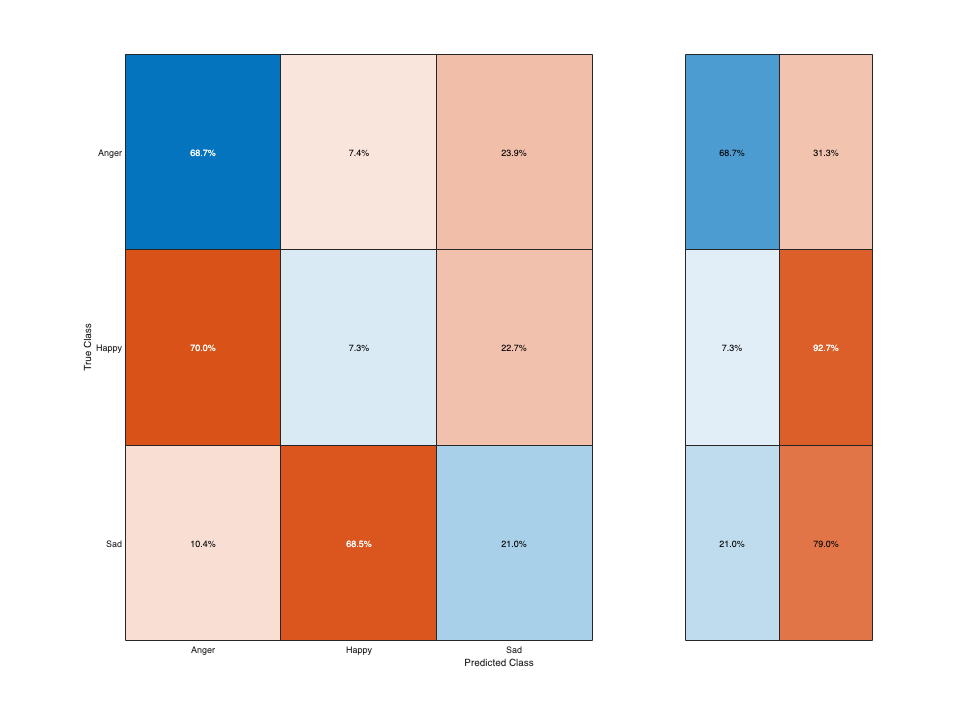

% Load combined model and predict on EmoDB (German)
load Workspace_Combined.mat net
load Workspace_EmoDB.mat sequencesTrain sequencesTest labelsTrain labelsTest
sequencesAll = vertcat(sequencesTrain, sequencesTest);
labelsAll = vertcat(labelsTrain, labelsTest);
predictionsAll = classify(net, sequencesAll);
labelsAll = removecats(labelsAll);
predictionsAll = removecats(predictionsAll);
figure; confusionchart(labelsAll, predictionsAll,'Normalization','row-normalized','RowSummary','row-normalized');

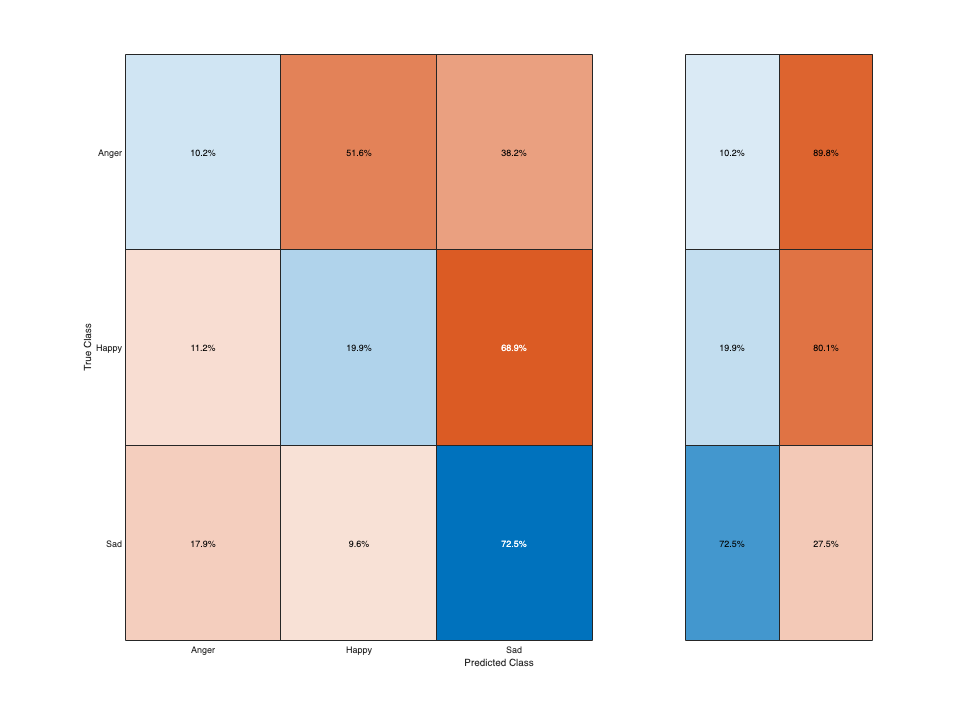

% Load combined model and predict on ShEMO (Persian)
load Workspace_Combined.mat net
load Workspace_ShEMO.mat sequencesTrain sequencesTest labelsTrain labelsTest
sequencesAll = vertcat(sequencesTrain, sequencesTest);
labelsAll = vertcat(labelsTrain, labelsTest);
predictionsAll = classify(net, sequencesAll);
labelsAll = removecats(labelsAll);
predictionsAll = removecats(predictionsAll);
figure; confusionchart(labelsAll, predictionsAll,'Normalization','row-normalized','RowSummary','row-normalized');